# First Order Two Dimensional Linear Systems

In this section, we try to solve $\mathbf{A}_1\mathbf{u}_x+\mathbf{A}_2\mathbf{u}_y+\mathbf{A}_0\mathbf{u}=\mathbf{f}(x,y)$ for $x,y\in\Omega$, $\Omega$ polygonal w.r.t Dirichlet boundary conditions $\mathbf{u}(x,y)=\mathbf{g}(x,y)$ for $x\in\partial\Omega$ where $\mathbf{A}_i\in\mathbb{R}^{m\times m}$ and $\mathbf{u},\mathbf{f},\mathbf{g}\in\mathbb{R}^{m\times 1}$. For ellpticity, we require $\mathrm{det}(\alpha_1\mathbf{A}_1+\alpha_2\mathbf{A}_2)\neq0$ for $\forall \alpha_1,\alpha_2\neq 0$. We start by forming a 2D polygonal mesh $\mathcal{M}=\{K_i\}_{i=1}^{M}$ for the domain $\Omega$.

% Construct the model
t = pi/20 : pi/20 : 2*pi;
Omega = polyshape([1.5*cos(t), nan, 0.5 + 0.5*cos(t), nan, 0.5 + 0.2*cos(t), nan, -0.6 + 0.3*cos(t)], ...
                  [1.5*sin(t), nan, 0.5*sin(t),       nan, 1 + 0.2*sin(t),   nan, -0.8 + 0.3*sin(t)]);
% Omega = polyshape(1.5*cos(t), 1.5*sin(t));

m  = 3 ;               % number of dependent variables
beta = 5 ; hmax=0.15 ; % discretization parameter, mesh size, hmin=hmax/beta 

model = Collocation2D(m, Omega);          % Construct the model   
model.discretize(hmax, beta, 'linear');   % Discretization
fprintf('%d Nodes (%d unknowns) and %d Elements generated', ...
        size(model.gm.Mesh.Nodes,2), size(model.gm.Mesh.Nodes,2)*m, size(model.gm.Mesh.Elements,2));

367 Nodes (1101 unknowns) and 630 Elements generated

`model.gm.Mesh.Nodes` stores the $(x,y)$ coordinates for each global vertex. 

`model.gm.Mesh.Elements `provides the local-to-global map and local vertices are stored in a counterclockwise order.

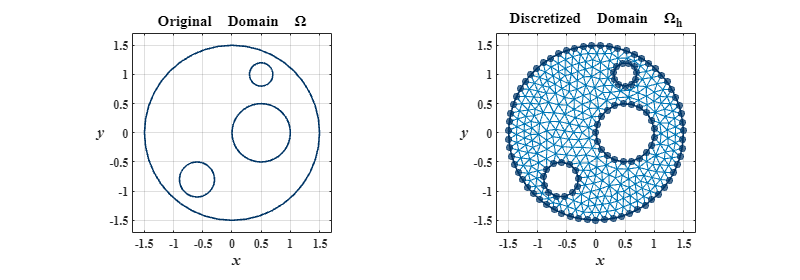

% Plot discretization
color = [ 0 ,  119, 182;
          0 ,  53 , 102]./255;
scatter_color = [0, 53, 102]./255;

if true 
    figure; set(gcf,'position',[0, 0, 1000, 350]); tiledlayout(1,2); 
    nexttile(1);
    h1 = model.gm.pdegplot(); % VertexLabels="on",EdgeLabels="on"
    h1.LineWidth = 1.5; h1.Color = color(2,:);
    hold on; box on, grid on; 
    xlim([-1.7 1.7]); ylim([-1.7 1.7]);
    xticks(-1.5:0.5:1.5); yticks(-1.5:0.5:1.5); xtickangle(0);
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
    ylabel("\it y",'FontSize', 15, 'FontWeight', 'bold', 'Rotation', 360);  
    title({'Original  Domain  \Omega'},'fontweight','bold','FontSize',14);

    nexttile(2);
    hm = model.gm.pdemesh(); %(ElementLabels="on", NodeLabels="on") ;
    hm(1).LineWidth = 1  ; hm(1).Color = color(1,:);
    hm(2).LineWidth = 1.5; hm(2).Color = color(2,:);
    hold on; box on, grid on; 
    xlim([-1.7 1.7]); ylim([-1.7 1.7]);
    xticks(-1.5:0.5:1.5); yticks(-1.5:0.5:1.5); xtickangle(0);
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
    xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
    ylabel("\it y",'FontSize', 15, 'FontWeight', 'bold', 'Rotation', 360);  
    title({'Discretized  Domain  \Omega_h'},'fontweight','bold','FontSize',14);

    edge = model.Edges;
    for i = 1:model.gm.NumEdges
        scatter(edge{i}(1:end-1,1), edge{i}(1:end-1,2), "filled", ...
                'MarkerEdgeColor', scatter_color, 'MarkerFaceColor', scatter_color, ...
                'MarkerFaceAlpha', 0.7);
    end
end

We approximate the solution with $C^0$ Lagrange elment $\mathrm{CG}_q$ where we first try $q=1$(linear elements). The degrees of freedom are given by evaluating the basis at all local vertices of the element. In element $K$ where $K=\triangle(v^K_1,v^K_2,v^K_3)$ is a trangle defined by three vertices $v^K_i(x^K_i,y^K_i)$, the nodal bases for som $p=(x,y)\in K$ are given by


$$\phi_1^K(p)\ =\ \frac{S_{\triangle}(p,v^K_2,v^K_3)}{S^K},$$



$$\phi_2^K(p)\ =\ \frac{S_{\triangle}(v^K_1,p,v^K_3)}{S^K},$$



$$\phi_3^K(p)\ =\ \frac{S_{\triangle}(v^K_1,v^K_2,p)}{S^K},$$


where 


$$S_{\triangle}(p_1,p_2,p_3)= \frac{1}{2}\left|\matrix{1\ x_1\ y_1\cr
1\ x_2\ y_2\cr
1\ x_3\ y_3  } \right| $$
 

is the area of the triangle $\triangle(p_1,p_2,p_3)$ s.t. $p_i=(x_i,y_i)$ and $p_1\to p_2\to p_3$ is given in a counterclockwise order  so that $S_{\triangle}(p_1,p_2,p_3)>0$; $S^K=S_\triangle(v^K_1,v^K_2,v^K_3)$ is the area of of the element. The solution ansatz is given as


$$\mathbf{u}(x)\approx\mathbf{u_C}(x)=\mathbf{C}\mathbf{\phi}(x)=\sum^n_{i=1}\mathbf{c}_i \cdot\phi_i(x),$$


where $\mathbf{c}_i$ is the $i_{th}$ column of $\mathbf{C}\in\mathbb{R}^{m\times n}$,  $\phi_i(x)$ is the global basis corresponding to the $i_{th}$ global degree of freedom (resp. the $i_{th}$ global vertex $v_i$ forming the discretized mesh).

% Sample Equation
% Sloution Benchmark: poisson
u    = @(x,y) [sin(x.^2 + y.^2);  2*x.*cos(x.^2 + y.^2); 2*y.*cos(x.^2 + y.^2)]; % u = [phi, v1, v2]
Dx_u = @(x,y) [2*x.*cos(x.^2 + y.^2);  2*cos(x.^2 + y.^2) - 4*x.^2.*sin(x.^2 + y.^2); -4*x.*y.*sin(x.^2 + y.^2)];
Dy_u = @(x,y) [2*y.*cos(x.^2 + y.^2);  -4*x.*y.*sin(x.^2 + y.^2); 2*cos(x.^2 + y.^2) - 4*y.^2.*sin(x.^2 + y.^2)];

% System Settings
num_eq = 4;
A1 = @(x,y) [1,0,0; 0,0,0; 0,-1,0; 0,0,1];
A2 = @(x,y) [0,0,0; 1,0,0; 0,0,-1; 0,-1,0];
A0 = @(x,y) [0,-1,0; 0,0,-1; 0,0,0; 0,0,0];
ff = @(x,y) 4*cos(x.^2 + y.^2) - 4*(x.^2 + y.^2).*sin(x.^2 + y.^2);
f  = @(x,y) [0 ; 0; -ff(x,y); 0];

num_cond = 2;
B1 = [];
B2 = [];
B0 = @(x,y) [1,0,0; 0, model.boundary_normal([x,y], 2), -model.boundary_normal([x,y], 1)];
g1 = @(x,y) sin(x.^2 + y.^2);
g2 = @(x,y) model.boundary_normal([x,y]) * [-2*y.*cos(x.^2 + y.^2); 2*x.*cos(x.^2 + y.^2)];
g  = @(x,y) [g1(x,y); g2(x,y)];

% Construct the model
model.fitInterior(A1, A2, A0, f, num_eq);
model.fitBoundary(B1, B2, B0, g, num_cond);
model.fitTrueSol(u, Dx_u, Dy_u);

The following functions help to sample points from the boundary and the within the domain.

% Coordinates of the closed boundary nodes
rng(42) ;  % random seed
N_loc = max( ceil((1/hmax.^4)/(size(model.gm.Mesh.Elements,2))), 8);  % 100
N_bc = max(ceil(1/hmax.^2), cellfun(@(x)size(x,1), model.Edges));
sampled_interior_nodes = model.sample_from_triangleMesh(model.gm.Mesh, N_loc); 

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


sampled_boundary_nodes = model.interp_multiedge_polyboundary(model.Edges, num2cell(N_bc)); 
N_Omega = size(sampled_interior_nodes, 1); N_Gamma = size(sampled_boundary_nodes, 1);
fprintf('N_Omega: %d, N_Gamma: %d, total: %d\neq_Omega: %d, eq_Gamma: %d, eq_total: %d', ...
         N_Omega, N_Gamma, N_Omega + N_Gamma, ...
         N_Omega*num_eq, N_Gamma*num_cond, N_Omega*num_eq + N_Gamma*num_cond);

N_Omega: 5040, N_Gamma: 199, total: 5239
eq_Omega: 20160, eq_Gamma: 398, eq_total: 20558

We now try to evaluate the residuals. For a given point $x\in K_i$ with a local-to-global map $\iota_{K_i}(j)=$ `gm.Mesh.Elements(j,i)` where $j=1,2,3$ we can evaluate the interior residuals


$$R_{\Omega}(x)=\mathbf{A}_1\partial_x\mathbf{u}_\mathbf{C}+\mathbf{A}_2\partial_y\mathbf{u}_{\mathbf{C}}+\mathbf{A}_0\mathbf{u}_{\mathbf{C}}-\mathbf{f}(x,y)$$


namely,

$R_{\Omega}(x)=

\left[\matrix{\ 

\mathcal{A}(\phi_1^K)
&
\mathcal{A}(\phi_2^K)
&
\mathcal{A}(\phi_3^K)

\    } \right]

\left[\matrix{ \mathbf{c}_{\iota_K(1)}  \cr  \mathbf{c}_{\iota_K(2)}\cr\mathbf{c}_{\iota_K(3)} } \right]-\mathbf{f}(x,y)$,

where $\mathcal{A}(\phi)=\mathbf{A}_1\partial_x\phi+\mathbf{A}_2\partial_y\phi+\mathbf{A}_0\phi$. Similar for the boundary residuals with weights specified by the diagonal matrix $\Lambda\in\mathbb{R}^{m\times m}$

$R_{\Gamma}(x)=\Lambda[\mathbf{u_C}(x)-\mathbf{g}(x)]
$,

there is 

$R_{\Omega}(x)=

\left[\matrix{\ 

\Lambda\phi_1^K
&
\Lambda\phi_2^K
&
\Lambda\phi_3^K

\    } \right]

\left[\matrix{ \mathbf{c}_{\iota_K(1)}  \cr  \mathbf{c}_{\iota_K(2)}\cr\mathbf{c}_{\iota_K(3)} } \right]-\Lambda\mathbf{g}(x,y)$.

Note if we write 

$\mathbf{B}^K_\Omega(x,y) = \left[\matrix{\ 

\mathcal{A}(\phi_1^K)
&
\mathcal{A}(\phi_2^K)
&
\mathcal{A}(\phi_3^K)

\    } \right]\in\mathbb{R}^{m\times 3m}$ for $x\in\mathrm{int}(\Omega)$, 

$\mathbf{B}^K_\Gamma(x,y) = \left[\matrix{\ 

\Lambda\phi_1^K
&
\Lambda\phi_2^K
&
\Lambda\phi_3^K

\    } \right]\in\mathbb{R}^{m\times 3m}$ for $x\in \Gamma=\partial\Omega$, 

a single point $x$ will generate $m$ lines in the final assembled system $\mathbf{B}\mathbf{c}=\mathbf{d}$ where 

$\mathbf{B}=\left[\matrix{ \mathbf{B}_\Omega  \cr  \mathbf{B}_\Gamma} \right]$ , $\mathbf{c}=\mathrm{vec}(\mathbf{C})=\left[\matrix{ \mathbf{c}_1  \cr  \vdots\cr\mathbf{c}_n} \right]$ , $\mathbf{d}=\left[\matrix{ \mathbf{d}_\Omega  \cr  \mathbf{d}_\Gamma} \right]$

and if we define slice $\mathbf{s}(i)=im-m+1:im$, there is

$\mathbf{B}_{\Omega}(\ \mathbf{s}(i)\ ,\  [\mathbf{s}\circ\iota_K(1) \ ,\  \mathbf{s}\circ\iota_K(2) \ ,\  \mathbf{s}\circ\iota_K(3)]\ ) := \mathbf{B}^K_\Omega(x_i,y_i)$,

$\mathbf{B}_{\Gamma}(\ \mathbf{s}(i)\ ,\  [\mathbf{s}\circ\iota_K(1) \ ,\  \mathbf{s}\circ\iota_K(2) \ ,\  \mathbf{s}\circ\iota_K(3)]\ ) := \mathbf{B}^K_\Gamma(\hat{x}_i,\hat{y}_i)$,

and 

$\mathbf{d}_{\Omega}(\ \mathbf{s}(i)\  ) := \mathbf{f}(x_i,y_i)$,

$\mathbf{d}_{\Gamma}(\ \mathbf{s}(i)\  ) := \Lambda\mathbf{g}(\hat{x}_i,\hat{y}_i)$,

for sets of selected points $\{{p}_i\}_{i=1}^{N_{\Omega}}\subset \Omega$ and $\{{\hat{p}}_i\}_{i=1}^{ N_{\Gamma} } \subset \Gamma$, $N=N_{\Omega}+N_{\Gamma}$.

% System assemble
Lambda = eye(num_cond)*(hmax^(-1.5)); % Skt Example para 200
[B_Omega, d_Omega, N_Omega] = model.Assemble_B_Omega(sampled_interior_nodes);
[B_Gamma, d_Gamma, N_Gamma] = model.Assemble_B_Gamma(sampled_boundary_nodes, Lambda);
B = [B_Omega ; B_Gamma];  d = [d_Omega ; d_Gamma];
c = B\d; model.C = model.reshape2mat(c);
fprintf('eq_Omega: %d, eq_Gamma: %d, eq_total: %d\nnum_eq: %d, num_unknown: %d, ratio m/n: %.2f\nL2 error: %.4f', ...
         N_Omega*num_eq, N_Gamma*num_cond, N_Omega*num_eq + N_Gamma*num_cond, ...
         size(B,1), size(B,2), size(B,1)/size(B,2), model.L2_error);

eq_Omega: 20160, eq_Gamma: 398, eq_total: 20558
num_eq: 20554, num_unknown: 1101, ratio m/n: 18.67
L2 error: 0.0533

% save('./data/2DsktSample/2DsktSampleModel_small.mat', 'model');

% Solution evaluation
grid_size = [200, 200]; 
[X, Y, in, XY] = model.OmegaMeshgrid(grid_size);
X_label = round(X(1,:),2); Y_label = round(Y(:,1),2);
u_fit = model.evaluate_LSFEM(XY); u_true = model.u(XY(:,1)', XY(:,2)');
u_fit  = model.reshapeRowsTo3D(u_fit,  grid_size(2), grid_size(1));
u_true = model.reshapeRowsTo3D(u_true, grid_size(2), grid_size(1)) .* in;

% Plot Result
figure; set(gcf,'position',[0, 0, 1000, 450]); tt = tiledlayout(2,4); 
t = linspace(0,2*pi,1000); CMAP1 = flipud(slanCM(97));

@author : slandarer


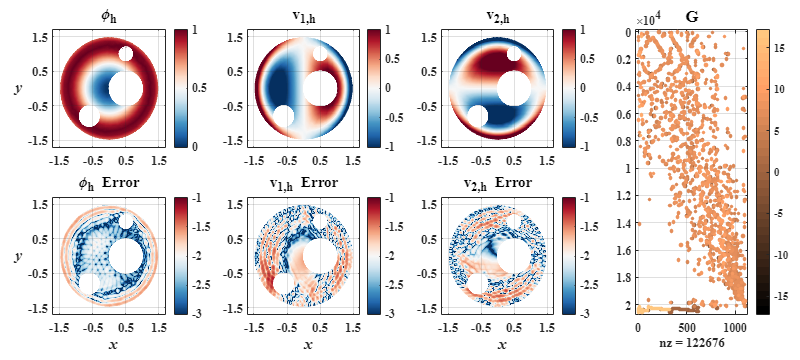


data = {u_fit(:,:,1), u_fit(:,:,2), u_fit(:,:,3),...
        log10(abs(u_fit(:,:,1) - u_true(:,:,1))),...
        log10(abs(u_fit(:,:,2) - u_true(:,:,2))),...
        log10(abs(u_fit(:,:,3) - u_true(:,:,3)))};

clims = {[0,1], [-1,1], [-1,1],...
         [-3,-1], [-3,-1], [-3,-1]};

titles = {'\phi_{h}', 'v_{1,h}', 'v_{2,h}',...
          '\phi_{h} Error', 'v_{1,h} Error', 'v_{2,h} Error'};

nexttile(4,[2,1]);
% cspy(B,'ColorMap','bone');
cspy(B,'ColorMap','copper');
grid on; box on;
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 11;
title('G','fontweight','bold','FontSize', 16);
xlim([-30, size(B,2)+30]); %xticks([]); 
ylim([-150, size(B,1)+160]); %yticks([]);
ax.XAxisLocation = 'bottom';

for i = 1:6
    if i <= 3
        ax = nexttile(i);
    else
        ax = nexttile(i+1);
    end

    % Plot data
    h = imagesc(X_label, Y_label, data{i}); 
    colormap(ax, CMAP1);
    set(h, 'AlphaData', ~isnan(data{i})); 
    set(gca,'YDir','normal'); 
    hold on; grid on; box on; 

    % Color bar
    c = colorbar; clim(clims{i}); set(c,'TickLabelInterpreter','tex');

    % XY axis
    xlim([-1.7 1.7]); ylim([-1.7 1.7]);
    xticks(-1.5:1:1.5); xtickangle(0);
    yticks(-1.5:1:1.5); 
    set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;

    if (i == 1) || (i==4)
        ylabel("\it y",'FontSize', 15, 'FontWeight', 'bold', 'Rotation', 360); 
    end

    if i >= 4
        xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
    end

    % Title
    title(titles{i},'fontweight','bold','FontSize',14)
    
    % Smooth out boundary
    plot(1.5*cos(t), 1.5*sin(t), 'LineWidth', 1.5, 'Color', [1,1,1]); 
    plot(0.5 + 0.5*cos(t), 0.5*sin(t), 'LineWidth', 1.5, 'Color', [1,1,1]); 
    plot(0.5 + 0.2*cos(t), 1 + 0.2*sin(t), 'LineWidth', 1.5, 'Color', [1,1,1]); 
    plot(-0.6 + 0.3*cos(t), -0.8 + 0.3*sin(t), 'LineWidth', 1.5, 'Color', [1,1,1]);     
end

tt.TileSpacing = 'compact'; tt.Padding = 'compact';

% Plot Lagrange Basis
figure; set(gcf,'position',[0, 0, 900, 450]); tiledlayout(3,6); 
colormap(flipud(slanCM(97)));

@author : slandarer


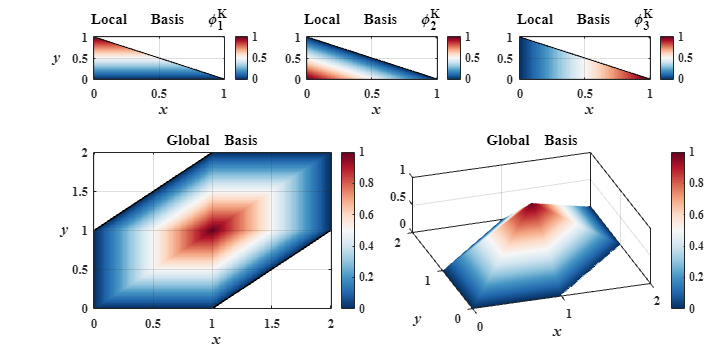

[x,y] = meshgrid(0:0.01:1);
% Local basis
nexttile(1,[1,2]);
phi1 = y; phi1( x+y > 1) = nan;
h = imagesc(x(1,:), y(:,1), phi1);
set(h, 'AlphaData', ~isnan(phi1)); set(gca,'YDir','normal'); hold on;
plot(x(1,:), 1-x(1,:), 'LineWidth', 1, 'Color', [0,0,0]); 
grid on; box on; 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;
title({'Local   Basis   \phi^K_1'},'fontweight','bold','FontSize',14)
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
ylabel("\it y ",'FontSize', 15, 'FontWeight', 'bold', 'Rotation', 360); 
c = colorbar; set(c,'TickLabelInterpreter','tex');

nexttile(3,[1,2]);
phi2 = 1-x-y; phi2( x+y > 1) = nan;
h = imagesc(x(1,:), y(:,1), phi2);
set(h, 'AlphaData', ~isnan(phi2)); set(gca,'YDir','normal'); hold on;
plot(x(1,:), 1-x(1,:), 'LineWidth', 1, 'Color', [0,0,0]); 
grid on; box on; 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;
title({'Local   Basis   \phi^K_2'},'fontweight','bold','FontSize',14)
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
c = colorbar; set(c,'TickLabelInterpreter','tex');

nexttile(5,[1,2]);
phi3 = x; phi3( x+y > 1) = nan;
h = imagesc(x(1,:), y(:,1), phi3);
set(h, 'AlphaData', ~isnan(phi3)); set(gca,'YDir','normal'); hold on;
plot(x(1,:), 1-x(1,:), 'LineWidth', 1, 'Color', [0,0,0]); 
grid on; box on; 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;
title({'Local   Basis   \phi^K_3'},'fontweight','bold','FontSize',14)
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold'); 
c = colorbar; set(c,'TickLabelInterpreter','tex');

% Global basis
ele1val = @(x,y) (x - y + 1).*( y <= x+1 ).*( x <= 1 ).*( y >= 1 );
ele2val = @(x,y) (2 - y).*( x>1 ).*( y>=x ).*( y<=2 );
ele3val = @(x,y) (2 - x).*( x<=2 ).*( y<x ).*( y>=1 );
ele4val = @(x,y) (- x + y + 1).*( y<1 ).*( y>=x-1 ).*( x>=1 );
ele5val = @(x,y) (y).*( x<1 ).*( y<=x ).*( y>=0 );
ele6val = @(x,y) (x).*( x>=0 ).*( y>x ).*( y<1 );
[x,y] = meshgrid(0:0.01:2);
phi = ele1val(x,y) + ele2val(x,y) + ele3val(x,y) + ele4val(x,y) + ele5val(x,y) + ele6val(x,y);
phi( y > x+1 ) = nan; phi( y < x-1 ) = nan;

nexttile(10,[2,3]);
surfc(x, y, phi, 'LineStyle', 'none'); alpha 1;
view([-18.60 55.80]); hold on; grid on; box on; 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;
title({'Global    Basis'},'fontweight','bold','FontSize',14)
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
ylabel("\it y ",'FontSize', 15, 'FontWeight', 'bold', 'Rotation', 360);
c = colorbar; set(c,'TickLabelInterpreter','tex');

nexttile(7,[2,3]);
phi( y > x+1 ) = nan; phi( y < x-1 ) = nan;
h = imagesc(x(1,:), y(:,1), phi);
set(h, 'AlphaData', ~isnan(phi)); set(gca,'YDir','normal'); hold on;
plot(x(1,:), x(1,:)-1, 'LineWidth', 1.5, 'Color', [0,0,0]);
plot(x(1,:), x(1,:)+1, 'LineWidth', 1.5, 'Color', [0,0,0]);
grid on; box on; 
set(gca,'fontname','times','FontWeight','Bold'); ax = gca; ax.FontSize = 12;
title({'Global    Basis'},'fontweight','bold','FontSize',14)
xlabel("\it x",'FontSize', 15, 'FontWeight', 'bold');
ylabel("\it y",'FontSize', 15, 'FontWeight', 'bold', 'Rotation', 360);  
c = colorbar; set(c,'TickLabelInterpreter','tex');